# [使用 MATLAB 函数模拟 RoadRunner 场景](https://ww2.mathworks.cn/help/roadrunner-scenario/ug/simulate-roadrunner-scenario-using-matlab.html)

此示例说明如何使用 MATLAB 函数在 RoadRunner Scenario 中运行和可视化场景。您可以使用 MATLAB 函数以编程方式控制 RoadRunner Scenario。您可以执行的常见编程任务包括：

- 打开和关闭 RoadRunner Scenario 应用程序。

- 打开、关闭和保存场景、场景和项目。

- 导入和导出场景。

RoadRunner Scenario 使您能够以交互方式设计和模拟场景中的代理。为了验证这些代理的行为，自动化运行和分析场景模拟结果的过程通常很有帮助。在该示例中，将了解如何使用自动驾驶工具箱启动 RoadRunner Scenario、配置和运行模拟，然后绘制模拟结果。

要运行此示例，您必须：

- 已创建 RoadRunner 项目文件夹。  

# **设置环境以启动 RoadRunner 场景**

要使用 MATLAB 函数以编程方式控制 RoadRunner Scenario，请使用`roadrunner`对象。默认情况下，`roadrunner `从您正在使用的平台（Windows® 或 Linux®）的默认安装文件夹中打开 RoadRunner。这些是平台的默认安装位置：

- Windows – C:\Program Files\RoadRunner *R20NNx* \bin\ win64

- Linux、Ubuntu® – /usr/local/RoadRunner_ *R20NNx* /bin/glnxa64

`R20NNx`是您正在使用的 MATLAB 版本。

如果您的 RoadRunner Scenario 安装位置与默认位置不同，请使用 MATLAB `settings`API 自定义 RoadRunner Scenario 安装文件夹的默认值。

# **打开 RoadRunner 场景会话**

您可以使用该 `roadrunner `函数创建 `roadrunner `对象并启动 RoadRunner 场景会话。该 `roadrunner `函数需要一个参数来指定 RoadRunner 项目的位置。RoadRunner 项目文件夹通常包含以下子文件夹：`Assets`、`Exports`、`Project`、`Scenarios`和 `Scenes`。

`roadrunner `通过指定创建项目的位置，使用该功能在 RoadRunner 中打开项目。此示例假定 RoadRunner 安装在其在 Windows 中的默认位置。

指定现有项目的路径。例如，此代码显示位于 上的项目的路径`C:\RR\MyProject`。该函数返回一个 `roadrunner `对象`rrApp，`该对象提供用于执行基本工作流任务（例如打开、关闭和保存场景和项目）的函数。

rrProj = "C:\workspace\BaiduSyncdisk\work\workspace\RoadRunner";
rrApp = roadrunner(rrProj, InstallationFolder="C:\matlab_2022b\software\RoadRunner R2022b\bin\win64");

`openScenario `在 RoadRunner Scenario 中使用函数打开已有场景，指定要打开的 `rrApp `对象和具体场景。`filename `比如打开 `TrajectoryCutIn `场景文件，这是 RoadRunner 工程中默认包含的场景。此函数通过 MATLAB 在 RoadRunner Scenario 应用程序中打开所需的场景。

openScenario(rrApp, "ChangSha.rrscenario"); % 位于工程路径下的Scenarios目录下

# **模拟场景**

将场景加载到 RoadRunner Scenario 后，通过使用 `createSimulation `函数创建模拟对象来自动执行模拟任务。模拟对象使您能够以编程方式与场景模拟进行交互。

将对象为函数`createSimulation `指定输入参数输入参数`rrApp`。该函数创建一个模拟对象，`rrSim`。

rrSim = createSimulation(rrApp);

将最长模拟时间设置为 10 秒。使用 `set `函数并指定 `rrSim `对象、要设置的变量的名称以及该变量的值作为输入参数。

maxSimulationTimeSec = 10;
set(rrSim, 'MaxSimulationTime',maxSimulationTimeSec);

启用模拟结果记录，以便您稍后可以绘制结果。

set(rrSim,"Logging","on");

开始模拟。使用 `while `循环监视仿真的状态，并等待仿真完成。

set(rrSim,"SimulationCommand","Start");
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end

# **绘制代理速度**

在本节中，您将从模拟中检索记录的参与者速度，并根据模拟时间绘制它们的大小。

从场景中获取记录的结果。使用该 `get `函数并将 `rrSim `对象和"指定`SimulationLog"`为输入参数。该函数返回模拟日志`rrLog`，其中包含有关场景模拟的信息。

rrLog = get(rrSim, "SimulationLog");

`TrajectoryCutIn scenario `包含两个演员。红色轿车 `Actor ID`设置为 `1,`，白色轿车 `Actor ID `设置为`2`。从模拟日志中获取这些参与者的记录速度。另外，从模拟日志中获取相应的模拟时间*。*

velocityAgent1 = get(rrLog,'Velocity','ActorID',1);
velocityAgent2 = get(rrLog,'Velocity','ActorID',2);
time = [velocityAgent1.Time];

该函数以向量形式返回红色轿车和白色轿车的速度，并将它们分别存储在`velMagAgent1`和`velMagAgent2`变量中。`norm`使用函数计算每个演员的速度大小。

velMagAgent1 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent1);
velMagAgent2 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent2);

`plot`使用函数绘制相对于模拟时间的代理速度。标记图表以及*x*和*y*轴。

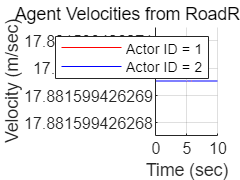

figure
hold on
plot(time,velMagAgent1,"r")
plot(time,velMagAgent2,"b")
grid on
title("Agent Velocities from RoadRunner Scenario")
ylabel("Velocity (m/sec)")
xlabel("Time (sec)")
legend("Actor ID = 1","Actor ID = 2")

请注意，演员的速度与他们在RoadRunner 场景的**逻辑编辑器**中的规范相对应**。**

# **绘制代理速度**

从 RoadRunner 场景中绘制车道并在地图上叠加车辆的位置。

使用 `getMap `函数从 RoadRunner 获取高精地图规格。请注意，该函数返回一个结构，其中一个字段包含有关车道的信息。

hdMap = getMap(rrSim);
lanes = hdMap.map.lanes;

使用循环遍历每个车道规格 `for `并绘制车道坐标。

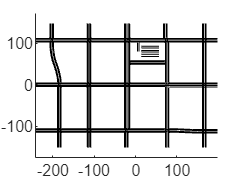

figure
hold on
for i = 1:numel(lanes)
    control_points = lanes(i).geometry.values;
    x_coordinates = arrayfun(@(cp) cp.x,control_points);
    y_coordinates = arrayfun(@(cp) cp.y,control_points);
    plot(x_coordinates, y_coordinates, 'black');
end
axis equal

提取车辆的位置并将它们绘制在车道上*。*

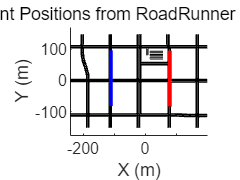

poseActor1 = rrLog.get('Pose','ActorID',1);
positionActor1_x = arrayfun(@(x) x.Pose(1,4),poseActor1);
positionActor1_y = arrayfun(@(x) x.Pose(2,4),poseActor1);
plot(positionActor1_x,positionActor1_y,"r","LineWidth",2)

poseActor2 = rrLog.get('Pose','ActorID',2);
positionActor2_x = arrayfun(@(x) x.Pose(1,4),poseActor2);
positionActor2_y = arrayfun(@(x) x.Pose(2,4),poseActor2);
plot(positionActor2_x,positionActor2_y,"b","LineWidth",2)

title("Agent Positions from RoadRunner Scenario")
ylabel("Y (m)")
xlabel("X (m)")

figure(gcf)

# **关闭场景会话**

要停止与 RoadRunner Scenario 交互，请关闭模拟。然后关闭应用程序。

close(rrApp)

关闭打开的图形。

close all

# **进一步探索**

在此示例中，您了解了使用 MATLAB 以编程方式连接到 RoadRunner Scenario 的基本功能。要进一步扩展此脚本，您可以：

- 改变场景和场景中的车辆参与者。

- 开发 MATLAB 和 Simulink 行为，发布角色行为，在 RoadRunner Scenario 模拟中模拟行为，控制模拟和访问模拟参数。